## Exponential stratification

### General

%Stratification
N0 = 3*2*pi/3600;
L_gm = 1300;
N2Func = @(z) N0*N0*exp(2*z/L_gm);
latitude=33;
f0=2*7.2921e-5*sind(latitude);
Lz=4000;
zvect=linspace(-Lz, 0, 1000);
N2=N2Func(zvect);
omega= N2Func(-2000);

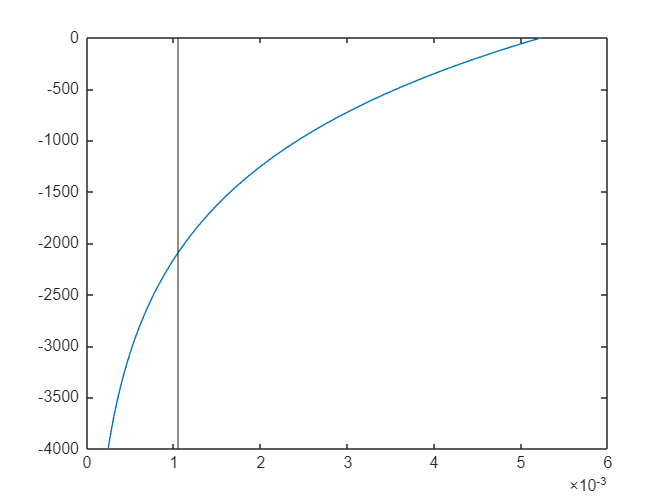

figure(1)
plot(sqrt(N2),zvect)
hold on
xline(omega)
hold of

### GM

phiGM= sqrt(N2)./N0;
gammaGM=N0./sqrt(N2);

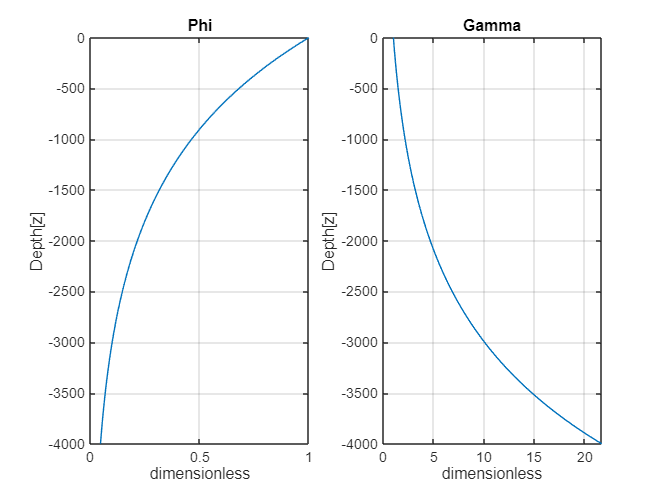

figure(2)
% First subplot (left panel)
subplot(1, 2, 1); 
plot(phiGM,zvect) 
title('Phi');
xlabel('dimensionless');
ylabel('Depth[z]');
grid on;

% Second subplot (right panel)
subplot(1, 2, 2); 
plot(gammaGM,zvect)
title('Gamma');
xlabel('dimensionless');
ylabel('Depth[z]');
grid on;

### Desaubies (this one is probably wrong)

omega= N2Func(-2000);
zvect=linspace(-2000, 0, 1000);
N2=N2Func(zvect);
j=1;

funcI= @(z) (N2Func(z) - f0^2)./(N2Func(z) - omega^2);
I=integral(funcI,-2000,0);


phiWKBJ=(1/I)*sqrt(N2-omega^2)*(1/N0);
gammaWKBJ=(1/I)*(1./sqrt(N2-omega^2))*(N0);


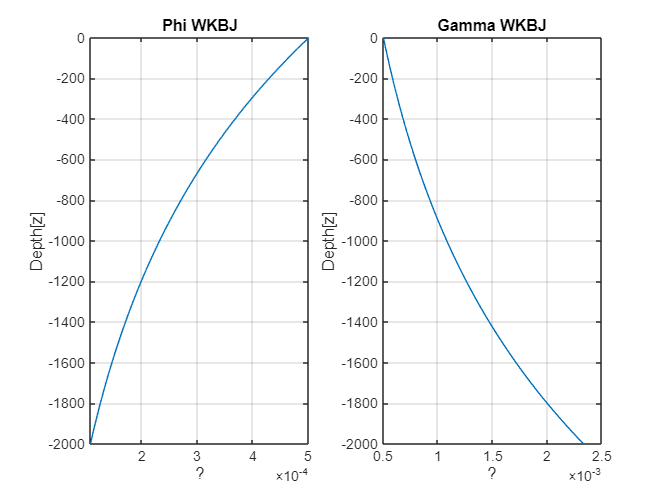

figure(3)
% First subplot (left panel)
subplot(1, 2, 1); 
plot(phiWKBJ,zvect) 
title('Phi WKBJ');
xlabel('?');
ylabel('Depth[z]');
grid on;

% Second subplot (right panel)
subplot(1, 2, 2); 
plot(gammaWKBJ,zvect)
title('Gamma WKBJ');
xlabel('?');
ylabel('Depth[z]');
grid on;

### Levine

NFunc = @(z) sqrt(N0*N0*exp(2*z/L_gm));
xiFunc = @(z) (1/N0)*integral(N2Func,zT,0);

zT=-2000;
DOmega = xi(zT);

N=NFunc(zvect);
xi=xiFunc(zvect);

phiBounded=sqrt(1./(N*N0))*sin(pi*j.*(xi./DOmega));
%gamma=;

figure(4)
% First subplot (left panel)
subplot(1, 2, 1); 
plot(phiBounded,zvect) 

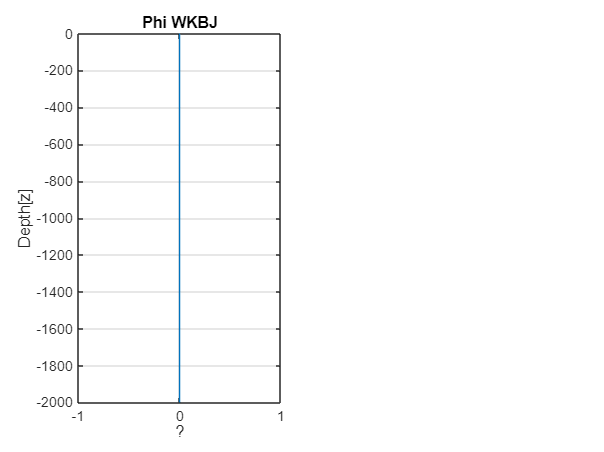

title('Phi WKBJ');
xlabel('?');
ylabel('Depth[z]');
grid on;